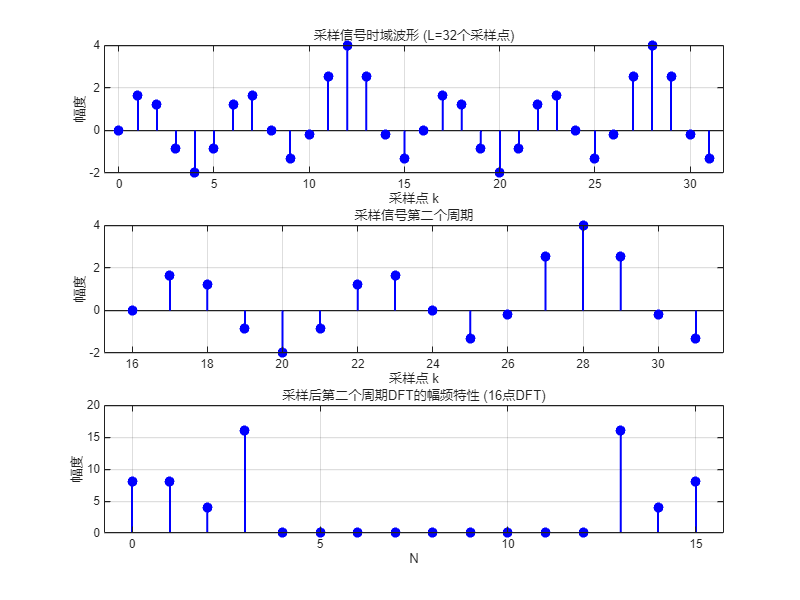

%% step1
clear; clc;
N = 16;          
L = 2 * N;       
f = 50;          
fs = N * f;      
T = 1 / fs;      
n = 0:T:(L-1)*T; % 采样点位置
k = 0:L-1;       % 采样点索引

s = 0.5*cos(0) + ...                 % A0=0.5, φ0=0
    1*cos(2*pi*f*n+pi/2) + ...       % A1=1, φ1=π/2
    0.5*cos(2*pi*2*f*n+pi) + ...     % A2=0.5, φ2=π
    2*cos(2*pi*3*f*n-pi/2);          % A3=2, φ3=-π/2

% 绘制时域采样信号
figure('Position', [100, 100, 800, 600]);
subplot(3, 1, 1);
stem(k, s, 'b', 'filled', 'LineWidth', 1.5);
xlabel('采样点 k');
ylabel('幅度');
title('采样信号时域波形 (L=32个采样点)');
grid on;
hold on;

%% step2
n1 = N*T:T:(L-1)*T;    % 第二个周期的采样时刻

% 重新计算第二个周期的信号
s_second = 0.5*cos(0) + ...                 
           1*cos(2*pi*f*n1+pi/2) + ...      
           0.5*cos(2*pi*2*f*n1+pi) + ...    
           2*cos(2*pi*3*f*n1-pi/2);         

S_second = fft(s_second, N);

% 绘制时域频谱
subplot(3, 1, 2);
stem(16:31, s_second, 'b', 'filled', 'LineWidth', 1.5);
xlabel('采样点 k');
ylabel('幅度');
title('采样信号第二个周期');
grid on;

% 绘制幅频特性
subplot(3, 1, 3);
stem( (0:N-1), abs(S_second), 'b', 'filled', 'LineWidth', 1.5);
xlabel('N');
ylabel('幅度');
title('采样后第二个周期DFT的幅频特性 (16点DFT)');
grid on;

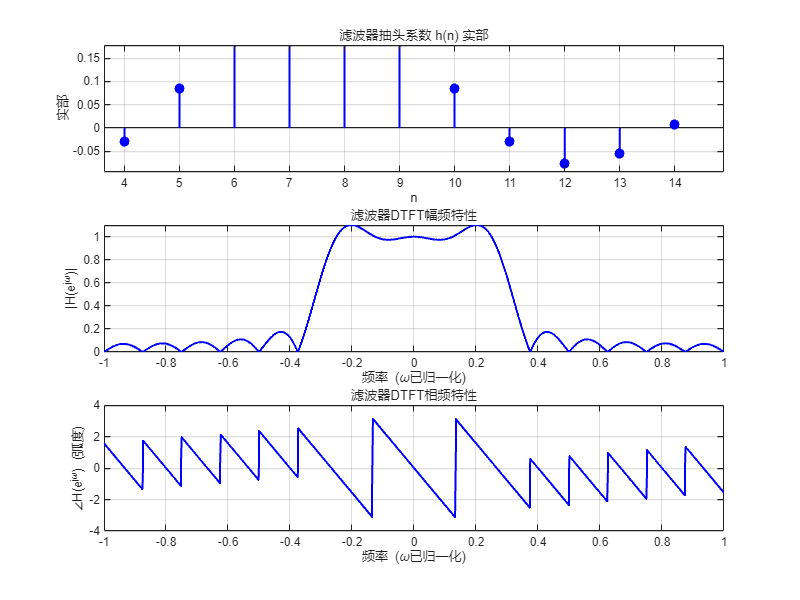

%% step3
clear; clc;
N = 16;          
k = 0:N-1;
H = zeros(1, N);

H(1) = 1;  % H(0) = 1, MATLAB索引从1开始
H(2) = exp(-1j*pi*(N-1)/N);  % H(1)
H(3) = exp(-1j*2*pi*(N-1)/N);  % H(2)
% H(4)到H(14)保持为0 (对应H(3)到H(13))
H(15) = -exp(-1j*14*pi*(N-1)/N);  % H(14)
H(16) = -exp(-1j*15*pi*(N-1)/N);  % H(15)

% IFFT计算h(n)
h = ifft(H, N);
figure('Position', [100, 100, 800, 600]);

% 子图1：滤波器抽头系数（实部）
subplot(3, 1, 1);
stem(0:N-1, real(h), 'b', 'filled', 'LineWidth', 1.5);
xlabel('n');
ylabel('实部');
title('滤波器抽头系数 h(n) 实部');
grid on;

% 计算DTFT
w = linspace(-pi, pi, 1000);  
Hw = zeros(1, length(w));

% H(e^jw) = sum_{n=0}^{N-1} h(n) * e^{-jwn}
for idx = 1:length(w)
    Hw(idx) = sum(h .* exp(-1j * w(idx) * (0:N-1)));
end

% 幅频特性
subplot(3, 1, 2);
plot(w/pi, abs(Hw), 'b', 'LineWidth', 1.5);
xlabel('频率 (\omega已归一化)');
ylabel('|H(e^{j\omega})|');
title('滤波器DTFT幅频特性');
grid on;

% 相频特性
subplot(3, 1, 3);
plot(w/pi, angle(Hw), 'b', 'LineWidth', 1.5);
xlabel('频率 (\omega已归一化)');
ylabel('∠H(e^{j\omega}) (弧度)');
title('滤波器DTFT相频特性');
grid on;

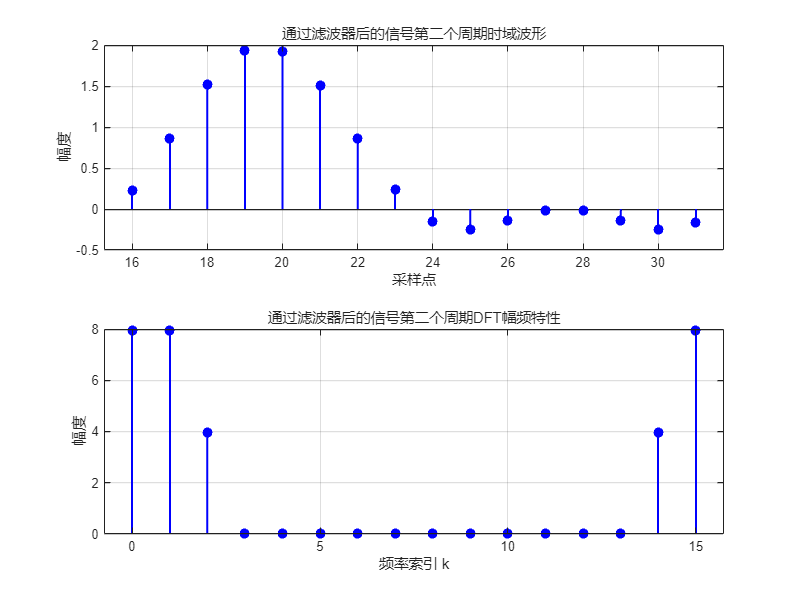

%% step4
clear; clc;
N = 16;         
L = 2 * N;      
f = 50;         
fs = N * f;      
T = 1 / fs;    
r = 0.999;       
n1 = 0:T:(L-1)*T; % 采样点位置

s = 0.5*cos(0) + ...                 % A0=0.5, φ0=0
    1*cos(2*pi*f*n1+pi/2) + ...      % A1=1, φ1=π/2
    0.5*cos(2*pi*2*f*n1+pi) + ...    % A2=0.5, φ2=π
    2*cos(2*pi*3*f*n1-pi/2);         % A3=2, φ3=-π/2

H = zeros(1, N);
H(1) = 1;  % H(0) = 1, MATLAB索引从1开始
H(2) = exp(-1j*pi*(N-1)/N);  % H(1)
H(3) = exp(-1j*2*pi*(N-1)/N);  % H(2)
% H(4)到H(14)保持为0 (对应H(3)到H(13))
H(15) = -exp(-1j*14*pi*(N-1)/N);  % H(14)
H(16) = -exp(-1j*15*pi*(N-1)/N);  % H(15)

x = CombFilter(s, N, r);  % 梳状滤波

% 并联谐振器处理
y1 = zeros(1, length(x));  % 初始化累加器
for i = 0: (N/2-1)
    y_resonator = Resonator2(x, N, r, i, H(i+1));  % 谐振器处理
    y1 = y1 + y_resonator;  % 累加所有谐振器输出
end

y = y1 / N;  % 归一化

% 提取第二个周期的输出 (n = N, N+1, ..., L-1)
y_second = y(N+1:L);  % 第二个周期的输出信号

% 绘制结果
figure('Position', [100, 100, 800, 600]);

% 子图1：第二个周期的时域波形
subplot(2, 1, 1);
stem(16:31, y_second, 'b', 'filled', 'LineWidth', 1.5);
xlabel('采样点');
ylabel('幅度');
title('通过滤波器后的信号第二个周期时域波形');
grid on;

% FFT
Y_second = fft(y_second, N);

% 子图2：第二个周期的幅频特性
subplot(2, 1, 2);
stem(0:N-1, abs(Y_second), 'b', 'filled', 'LineWidth', 1.5);
xlabel('频率索引 k');
ylabel('幅度');
title('通过滤波器后的信号第二个周期DFT幅频特性');
grid on;

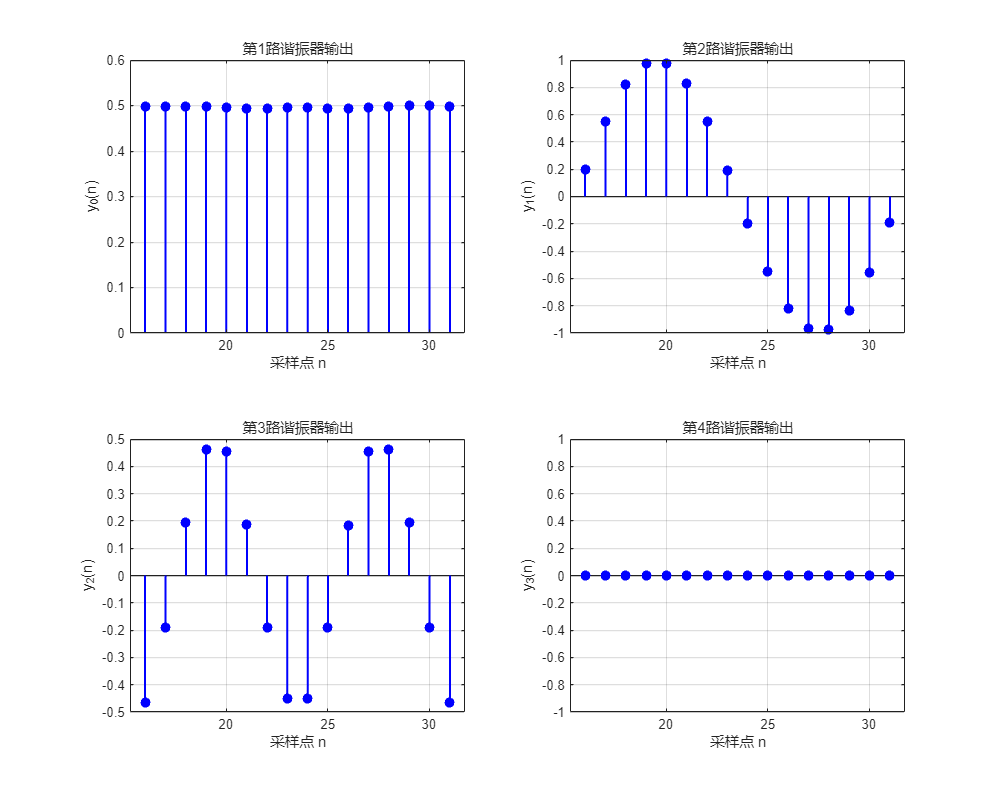

%% step5
i=N:1:L-1;
figure('Position', [100, 100, 1000, 800]);

% 第1路谐振器
y0 = Resonator2(x, N, r, 0, H(1));
subplot(2, 2, 1);
stem(i, y0(i+1)/N, 'b', 'filled', 'LineWidth', 1.5);
title('第1路谐振器输出');
xlabel('采样点 n'); ylabel('y_0(n)');
grid on;

% 第2路谐振器
y1 = Resonator2(x, N, r, 1, H(2));
subplot(2, 2, 2);
stem(i, y1(i+1)/N, 'b', 'filled', 'LineWidth', 1.5);
title('第2路谐振器输出');
xlabel('采样点 n'); ylabel('y_1(n)');
grid on;

% 第3路谐振器 
y2 = Resonator2(x, N, r, 2, H(3));
subplot(2, 2, 3);
stem(i, y2(i+1)/N, 'b', 'filled', 'LineWidth', 1.5);
title('第3路谐振器输出');
xlabel('采样点 n'); ylabel('y_2(n)');
grid on;

% 第4路谐振器
y3 = Resonator2(x, N, r, 3, H(4));  % 修正：Order应为3，不是0
subplot(2, 2, 4);
stem(i, y3(i+1)/N, 'b', 'filled', 'LineWidth', 1.5);
title('第4路谐振器输出');
xlabel('采样点 n'); ylabel('y_3(n)');
grid on;

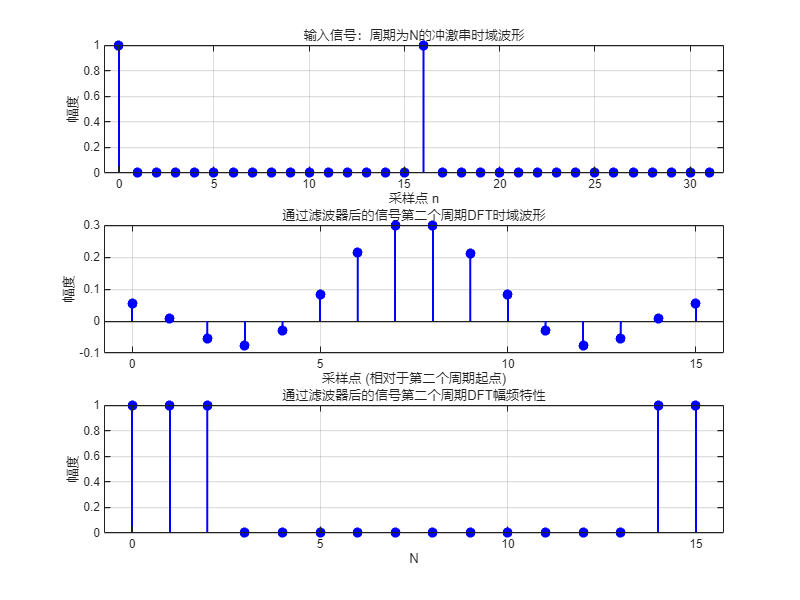

%% step6
clear; clc;
N = 16;          
L = 2 * N;       
f = 50;          
fs = N * f;      
T = 1 / fs;      
r = 0.999;       

H = zeros(1, N);
H(1) = 1;  % H(0) = 1, MATLAB索引从1开始
H(2) = exp(-1j*pi*(N-1)/N);  % H(1)
H(3) = exp(-1j*2*pi*(N-1)/N);  % H(2)
% H(4)到H(14)保持为0 (对应H(3)到H(13))
H(15) = -exp(-1j*14*pi*(N-1)/N);  % H(14)
H(16) = -exp(-1j*15*pi*(N-1)/N);  % H(15)

% 构建周期为N的冲激串信号
s1 = [1 zeros(1, N-1) 1 zeros(1, N-1)]; 

% 绘制输入冲激串的时域波形
figure('Position', [100, 100, 800, 600]);
subplot(3, 1, 1);
stem(0:L-1, s1, 'b', 'filled', 'LineWidth', 1.5);
xlabel('采样点 n');
ylabel('幅度');
title('输入信号：周期为N的冲激串时域波形');
grid on;

x1 = CombFilter(s1, N, r);  % 梳状滤波

y1 = zeros(1, length(x1)); 
for i = 0: (N/2-1)
    y_resonator = Resonator2(x1, N, r, i, H(i+1)); 
    y1 = y1 + y_resonator;  
end

y = y1 / N;  

% 提取第二个周期的输出 (n = N, N+1, ..., L-1)
y_second = y(N+1:L);  % 第二个周期的输出信号

% 子图2：第二个周期的时域波形
subplot(3, 1, 2);
stem(0:length(y_second)-1, y_second, 'b', 'filled', 'LineWidth', 1.5);
xlabel('采样点 (相对于第二个周期起点)');
ylabel('幅度');
title('通过滤波器后的信号第二个周期DFT时域波形');
grid on;

% FFT
Y_second = fft(y_second, N);

% 子图3：第二个周期的幅频特性
subplot(3, 1, 3);
stem(0:N-1, abs(Y_second), 'b', 'filled', 'LineWidth', 1.5);
xlabel('N');
ylabel('幅度');
title('通过滤波器后的信号第二个周期DFT幅频特性');
grid on;